# Ejercicios raices

5.7 Determine the roots of f (x) = −12 − 21*x + 18*x^2 − 2.75*x^3 graphically. In addition, determine the first root of the function with bisection

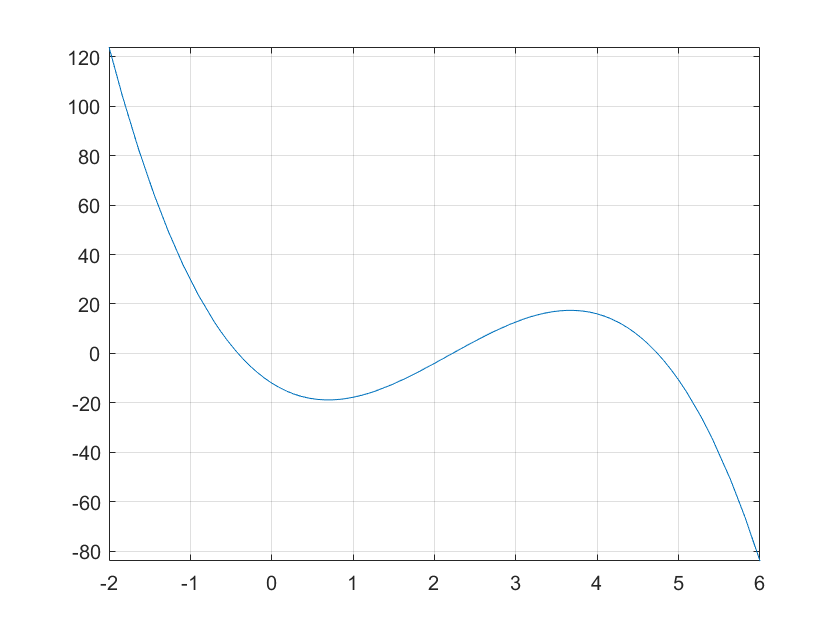

%
f=@(x) -12 -21*x +18*x.^2-2.75*x.^3;
fplot(f,[-2,6]);
grid on;

%Parece que los ceros están entre los valores de x: (-1,0), (2,3) y (4,5)


This plot indicates that roots are located at about –0.4, 2.25 and 4.7. La primera raíz está en [-1,0].

%
[x,iteraciones]=bisect(f,-2,6);
x

x = -0.4147

iteraciones

iteraciones = 57

%Se puede observar que por las derivadas de la función, es posible
%encontrar una raíz, pero para encontrar la raíz deseada es necesario
%elegir un valor de inicio que nos acerque a la raíz que estamos buscando.
%En este caso, al utilizar valores mayores a -9, al hacer las operaciones
%de la función y derivada, termina encontrando la 2da y 3er raíz.
[x,iteraciones]=newRap(f,-9);
x

x = -0.4147

iteraciones

iteraciones = 9


[x,iteraciones]=secante(f,-5,-9);
x

x = -0.4147

iteraciones

iteraciones = 11


[x,iteraciones]=interpolacion(f,-2,1);
x

x = -0.4147

iteraciones

iteraciones = 58

5.8 Locate the first nontrivial root of sin(x) = x^2 where x is in radians. Use a graphical technique and bisection.

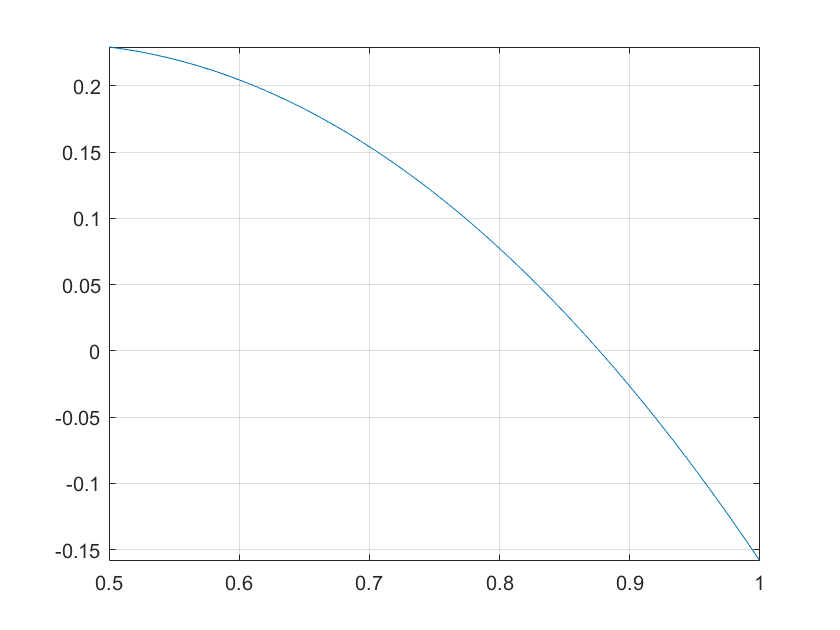

%La trivial es 0. La no trivial está entre 0.5 y 1
f=@(x) sin(x)-x.^2;
fplot(f,[0.5,1]);
grid on;

[x,iteraciones]=bisect(f,0.5,1);
x

x = 0.8767

iteraciones

iteraciones = 52

%En este caso, al utilizar valores mayores a 1, al hacer las operaciones
%de la función y derivada, termina encontrando la raíz no trivial, pero en
%otro caso encontramos la raíz x=0.
[x,iteraciones]=newRap(f,10);
x

x = 0.8767

iteraciones

iteraciones = 8

5.9 Determine the positive real root of ln(x^2) = 0.7 (a) graphically, (b) using the bisection method, with initial guesses of xl = 0.5 and xu = 2

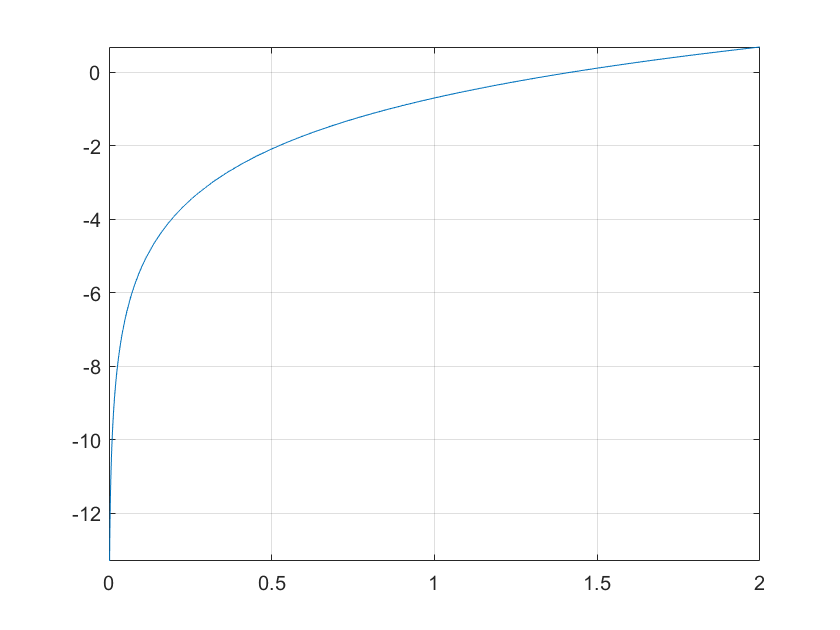

%La solución se encuentra entre 1 y 1.5
f=@(x) log(x.^2)-0.7;
fplot(f,[0,2]);
grid on;

[x,iteraciones]=bisect(f,1,1.5);
x

x = 1.4191

iteraciones

iteraciones = 51


%En este caso, al utilizar valores mayores a -10, 
%de la función y derivada, termina encontrando la única raíz. Pero si se
%elige algún valor mayor a 1, termina marcando x=Inf.
[x,iteraciones]=newRap(f,-1);
x

x = -1.4191

iteraciones

iteraciones = 5

Ejercicio 6.22

R=3;
f=@(h) (pi*h.^2)*(3*R-h)/3 - 30;
[x,iteraciones]=bisect(f,2,R);
x

x = 2.0269

iteraciones

iteraciones = 51

Escribe aquí la función bisección

function [x,i]=bisect(f,a,b)
    if f(a)*f(b)>0, error('f(a) y f(b) deben tener distinto signo'), end
    xizq=a;
    xder=b;
    x=(xizq+xder)/2;
    xprev=b;
    i=1;
    MAX=1000;
    while abs((x-xprev)/x)>eps && f(x)~=0 && i<MAX
        if f(x)*f(xizq)>0
            xizq=x;
        else
            xder=x;
        end
        i=i+1;
        xprev=x;
        x=(xizq+xder)/2;
    end
end

function [x,i]=newRap(f,xi)
    %xn+1=xn-f(xn)/f´(xn)
    fsym=sym(f);
    dfs=diff(fsym);
    df=matlabFunction(dfs);
    xp=xi;
    i=0;
    x=xp-f(xp)/df(xp);
    MAX=1000;
    if dfs==0 && f(x)~=0, error('La derivada de la función es 0, raíces son imaginarias'), end
    while abs((x-xp)/x)>eps && f(x)~=0 && i<MAX
        xp=x;
        x=xp-f(xp)/df(xp);
        i=i+1;
    end
end

function [x,i]=secante(f,xact,xprev)
    %xn+1=xn-f(xn)/f´(xn)
    i=0;
    sn=(f(xact)-f(xprev))/(xact-xprev);
    x=xact-f(xact)/sn;
    MAX=1000;
    while abs((x-xact)/x)>eps && f(x)~=0 && i<MAX
        xprev=xact;
        xact=x;
        sn=(f(xact)-f(xprev))/(xact-xprev);
        x=xact-f(xact)/sn;
        i=i+1;
    end
end

function [x,i]=interpolacion(f,x0,x1)
    if f(x0)*f(x1)>0, error('f(a) y f(b) deben tener distinto signo'), end
    xprev=x1;
    xder=x0;
    xizq=x1;
    x=xder-f(xder)*(xder-xizq)/(f(xder)-f(xizq));
    i=1;
    MAX=1000;
    while abs((x-xprev)/x)>eps && f(x)~=0 && i<MAX
        xprev=x;
        x=xder-f(xder)*(xder-xprev)/(f(xder)-f(xprev));
        i=i+1;
    end
end